First set the Name, Width and Hight of you massspec part

Name = 'Palladium_HPCT_0-14';
 

Then mark the mass spectra and enter the following code

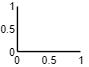

spec = gco;
set(spec,'yticklabel',{});
set(spec,'xticklabel',{});
set(gca,'YColor',[0 0 0]);
set(gca,'XColor',[0 0 0]);
xlabel(spec, '');
ylabel(spec, '');

Afterwards change the width and hight to what you want

spec.Parent.Units = 'centimeters';

Unrecognized method, property, or field 'Parent' for class 'matlab.graphics.GraphicsPlaceholder'.

Now Enter the following code and your massspec will be saved as .pdf

screenposition = spec.Parent.OuterPosition;
set(gcf,...
    'PaperPosition',[0 0 screenposition(3:4)],...
    'PaperSize',[screenposition(3:4)]);
exportgraphics(spec.Parent,strcat(Name,'_MassSpec','.pdf'),'ContentType','vector')
saveas(spec,strcat(Name,'_MassSpec'))